# 21960197 向平 Assignment

# Ex 2.5.2

Use the Jacobi Method to solve the sparse system within three correct decimal places (forward error in the infinity norm) for n = 100. The correct solution is [1,−1,1,−1, . . . ,1,−1]. Report the number of steps needed and the backward error. The system is


$$\left[\begin{array}{ccccc}{2} & {1} & {} & {} & {} \\ {1} & {2} & {1} & {} & {} \\ {} & {\ddots} & {\ddots} & {\ddots} & {} \\ {} & {} & {1} & {2} & {1} \\ {} & {} & {} & {1} & {2}\end{array}\right]\left[\begin{array}{c}{x_{1}} \\ {} \\ {\vdots} \\ {x_{n}}\end{array}\right]=\left[\begin{array}{r}{1} \\ {0} \\ {\vdots} \\ {0} \\ {-1}\end{array}\right]$$


% Jacobi method
% matrix setup
n = 100;
e = ones(n,1);
A = spdiags([e,2*e,e],-1:1,n,n);
D = 2*eye(n);
L = tril(A)-D;

b = zeros(n,1);
b(1) = 1;
b(n) = -1;

x_c = ones(n,1);
x_c(2:2:end) = -1;
x = zeros(n,1);
iteration = 1;
while norm((x_c-x),"inf")>10^(-2)
    iteration = iteration +1;
    % matrix calculation instead of for-loop
    x = D\(b-(L+L')*x);
end
x

x =     0.9997
   -0.9994
    0.9991
   -0.9988
    0.9985
   -0.9981
    0.9978
   -0.9975
    0.9972
   -0.9969


iteration

iteration = 10018

backward_error = norm(A*x-b,"inf")

backward_error = 9.6740e-06

# Ex 2.5.6

Carry out the steps of Computer Problem 2 for (a) Gauss–Seidel Method and (b) SOR with ω = 1.5.

% Gauss-Seidel method
% matrix setup
n = 100;
e = ones(n,1);
A = spdiags([e,2*e,e],-1:1,n,n);
b = zeros(n,1);
b(1) = 1;
b(n) = -1;
x_c = ones(n,1);
x_c(2:2:end) = -1;
x = zeros(n,1);
iteration = 1;
while  norm((x_c-x),"inf")>10^(-2)
    iteration = iteration +1;
    % for-loop for simplification
    for i=1:n
        if i==1
            x(i) = (1-x(i+1))/2;
        elseif i==n
            x(i) = (-1-x(i-1))/2;
        else
            x(i) = (-x(i-1)-x(i+1))/2;
        end   
    end
end

x

x =     0.9997
   -0.9994
    0.9990
   -0.9987
    0.9984
   -0.9981
    0.9978
   -0.9975
    0.9972
   -0.9969


iteration

iteration = 5011

backward_error = norm((A*x-b),"inf")

backward_error = 9.6744e-06

% SOR method
% matrix setup
w = 1.5;
n = 100;
e = ones(n,1);
A = spdiags([e,2*e,e],-1:1,n,n);
b = zeros(n,1);
b(1) = 1;
b(n) = -1;
x_c = ones(n,1);
x_c(2:2:end) = -1;
x = zeros(n,1);
iteration = 1;
while  norm((x_c-x),"inf")>10^(-3)
    iteration = iteration +1;
    % for-loop for simplification
    for i=1:n
        if i==1
            x(i) = (1-w)*x(i) + w*(1-x(i+1))/2;
        elseif i==n
            x(i) = (1-w)*x(i) + w*(-1-x(i-1))/2;
        else
            x(i) = (1-w)*x(i) + w*(-x(i-1)-x(i+1))/2;
        end   
    end
end
x

x =     1.0000
   -0.9999
    0.9999
   -0.9999
    0.9998
   -0.9998
    0.9998
   -0.9997
    0.9997
   -0.9997


iteration

iteration = 2461

backward_error = norm((A*x-b),"inf")

backward_error = 9.7363e-07

**From the above results, we can observe the needed iteration steps of the SOR method is the least, then the Gauss-Seidel method, and the Jacobi method needs the most steps. Meanwhile, the SOR method gives the smallest error.**

# Ex 2.6

Let A be the n × n matrix with n = 1000 and entries $A\left(i,i\right)=i,A\left(i,i+1\right)=A\left(i+1,i\right)=\frac{1}{2},A\left(i,i+2\right)=A\left(i+2,i\right)=\frac{1}{2}$ , for all i that fit within the matrix. (a) Print the nonzero structure spy(A). (b) Let $x_e$ be the vector of n ones. Set $b={A\;x}_e$, and apply the Conjugate Gradient Method, without preconditioner, with the Jacobi preconditioner, and with the Gauss–Seidel preconditioner. Compare errors of the three runs in a plot versus step number.

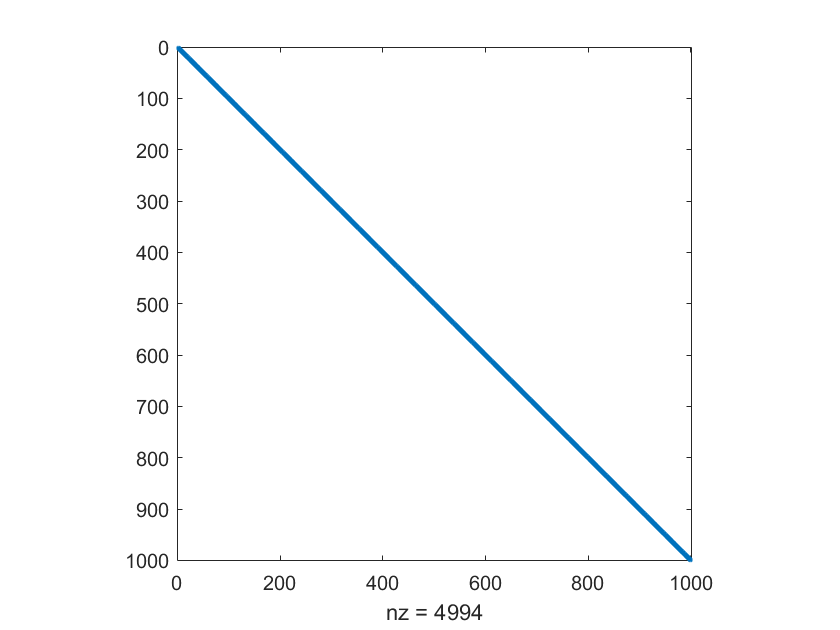

% matrix setup

n = 1000;
e = ones(n,1);
dia = (1:1:n)';
A = spdiags([0.5*e,0.5*e,dia,0.5*e,0.5*e],-2:2,n,n);
spy(A)

% without preconditioner
xe = ones(n,1);
b = A*xe;
x = 0.5*ones(n,1);
error_1 = zeros(n,1);
d = b-A*x;
r = b-A*x;
for i=1:n
    if r<=eps
        break;
    end
    a = (d'*r)/(d'*A*d);
    x = x+a*d;
    r = b-A*x;
    beta = -1*(d'*A*r)/(d'*A*d);
    d = r+beta*d;
    error_1(i) = norm(x-xe,"inf");
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


% with Jacobi preconditioner

M = diag(1:n);
M_ = inv(M);
x = 0.5*ones(n,1);
error_2= zeros(n,1);
r = b-A*x;
%d = M_*r;  % inv(M)*r = M\r
d = M\r;
z = d;
for i=1:n
    if r<=eps
        break;
    end
    a = (r'*z)/(d'*A*d);
    x = x + a*d;
    r_old = r;
    z_old = z;
    r = r - a*A*d;
    %z = M_*r;
    z = M\r;
    beta = (r'*z)/(r_old'*z_old);
    d = z+beta*d;
    error_2(i) = norm(x-xe,"inf");
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



% with Gauss-Seidel preconditioner
xe = ones(n,1);
b = A*xe;
D = diag(1:n);
L = tril(A)-D;
% M = (D+L)*inv(D)*(D+L');
M = (D+L)/D*(D+L');
M_ = inv(M);
x = 0.5*ones(n,1);
error_3 = zeros(n,1);
r = b-A*x;
% d = M_*r;  % inv(M)*r = M\r
d = M\r;
z = d;
for i=1:n
    if r<=eps
        break;
    end
    a = (r'*z)/(d'*A*d);
    x = x + a*d;
    r_old = r;
    z_old = z;
    r = r - a*A*d;
    %z = M_*r;
    z = M\r;
    beta = (r'*z)/(r_old'*z_old);
    d = z+beta*d;
    error_3(i) = norm(x-xe,"inf");
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


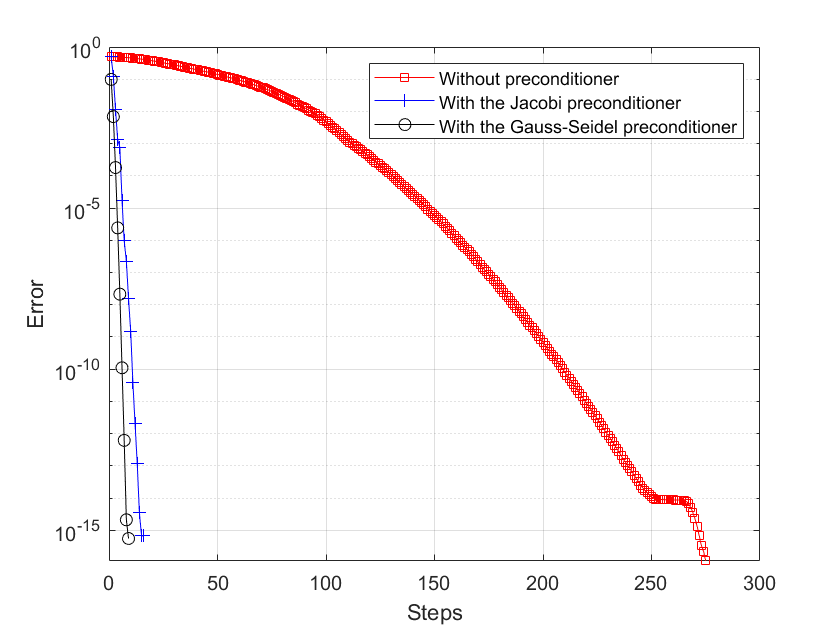

steps = 1:n;
semilogy(steps,error_1,'r-s',steps,error_2,'b-+',steps,error_3,'k-o');
grid on;
xlabel('Steps');
ylabel('Error');
legend('Without preconditioner','With the Jacobi preconditioner','With the Gauss-Seidel preconditioner')

**From the above plot, the error of the Conjugate Gradient Method with the Gauss-Seidel preconditioner decays most quickly, and the next is the Conjugate Gradient Method with the Jacobi preconditioner, and the decline rates of both method is close. However, the Gradient Gradient method withoud preconditioners declines much more slowly.**